# TAP 2 part. A (ADPLM)

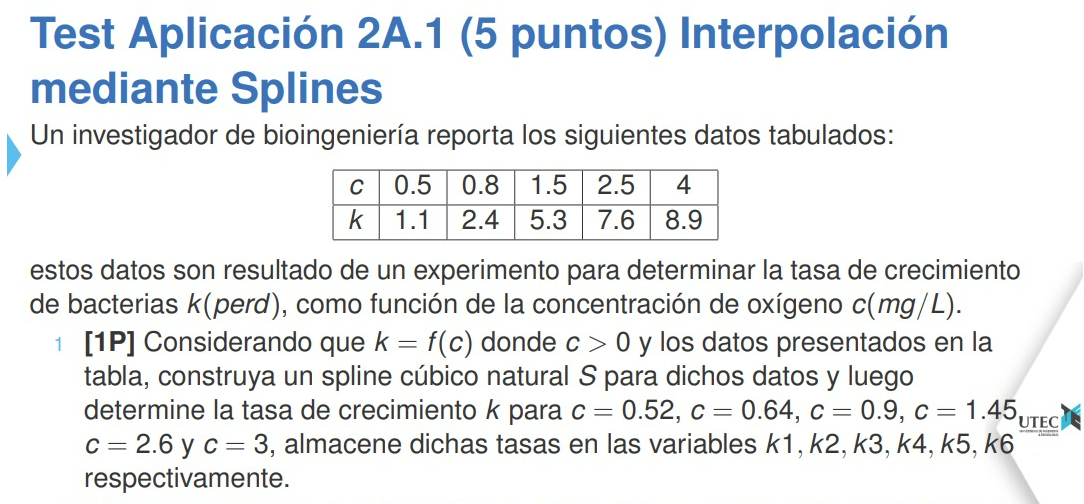

%Solución
c = [0.5, 0.8, 1.5, 2.5, 4]

c =    0.500000000000000   0.800000000000000   1.500000000000000   2.500000000000000   4.000000000000000


k = [1.1, 2.4, 5.3, 7.6, 8.9]

k =    1.100000000000000   2.400000000000000   5.300000000000000   7.600000000000000   8.900000000000000



S=splinenatural(c,k) 

S =    0.270620148792741                   0   4.308977519941985   1.100000000000000
  -0.836078593874100   0.243558133913467   4.382044960116025   2.400000000000000
   0.318216098622191  -1.512206913222143   3.493990814599952   5.300000000000000
   0.123901914967905  -0.557558617355571   1.424225284022238   7.600000000000000


k1 = S(1,1)*(0.52-0.5)^3 + S(1,2)*(0.52-0.5)^2 + S(1,3)*(0.52-0.5) + S(1,4)

k1 =    1.186181715360030


k2 = S(1,1)*(0.64-0.5)^3 + S(1,2)*(0.64-0.5)^2 + S(1,3)*(0.64-0.5) + S(1,4)

k2 =    1.703999434480165


k3 = S(2,1)*(0.9-0.8)^3 + S(2,2)*(0.9-0.8)^2 + S(2,3)*(0.9-0.8) + S(2,4)

k3 =    2.839803998756863


k4 = S(2,1)*(1.45-0.8)^3 + S(2,2)*(1.45-0.8)^2 + S(2,3)*(1.45-0.8) + S(2,4)

k4 =    5.121624451811181


k5 = S(4,1)*(2.6-2.5)^3 + S(4,2)*(2.6-2.5)^2 + S(4,3)*(2.6-2.5) + S(4,4)

k5 =    7.736970844143636


k6 = S(4,1)*(3-2.5)^3 + S(4,2)*(3-2.5)^2 + S(4,3)*(3-2.5) + S(4,4)

k6 =    8.188210727043215


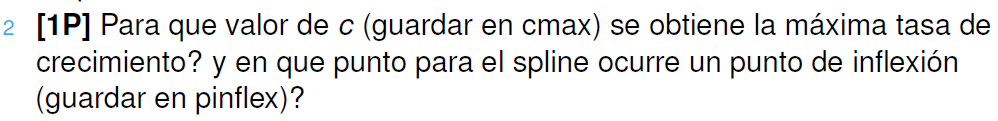

%Solución
syms x
F = @(x) (S(2,1)*(x-0.8)^3 + S(2,2)*(x-0.8)^2 + S(2,3)*(x-0.8) + S(2,4) - 5)

F = function_handle with value:
    @(x)(S(2,1)*(x-0.8)^3+S(2,2)*(x-0.8)^2+S(2,3)*(x-0.8)+S(2,4)-5)


resp = newton(F,1,1e-4);
c5 = resp(end)

c5 =    1.416984111676849


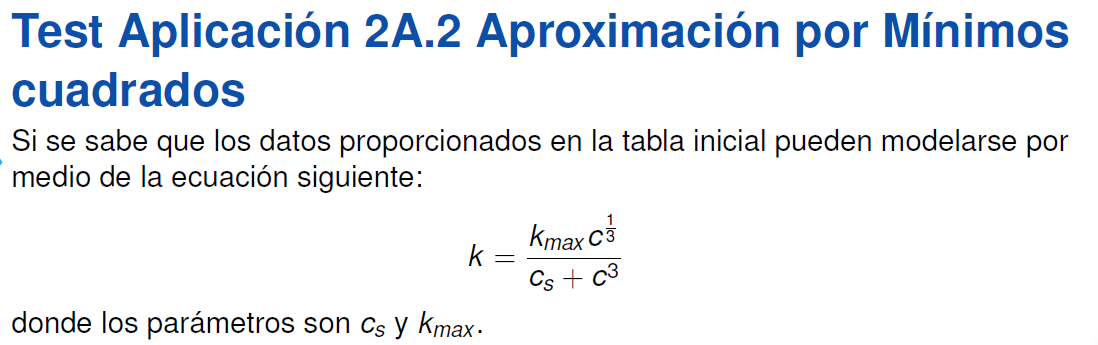

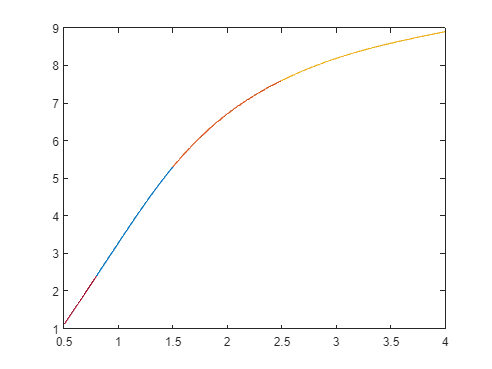

%Solución
format long
k = [1.1 2.4 5.3 7.6 8.9];
c = [0.5 0.8 1.5 2.5 4];
k_c = splinenatural(c,k);


k = [1.1 2.4 5.3 7.6 8.9]';
c = [0.5 0.8 1.5 2.5 4]';

%aplicando fórmula:
M = [c.^2 -1*k]

M =    0.250000000000000  -1.100000000000000
   0.640000000000000  -2.400000000000000
   2.250000000000000  -5.300000000000000
   6.250000000000000  -7.600000000000000
  16.000000000000000  -8.900000000000000


b = (k).*(c.^2)

b = 1.0e+02 *

   0.002750000000000
   0.015360000000000
   0.119250000000000
   0.475000000000000
   1.424000000000000


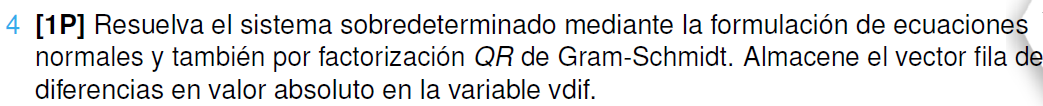

%Solución
EC_norm_sol = inv(M'*M)*M'*b

EC_norm_sol =   10.010248491812225
   1.993231191528652



%QR Gram-Schmidt
[Q,R] = gs_c(M);
b = Q'*b;
solu_gs = sustireg(R,b)

solu_gs =   10.010248491812224
   1.993231191528651


vdif = [abs(solu_gs - EC_norm_sol)]'

vdif = 1.0e-14 *

   0.177635683940025   0.155431223447522


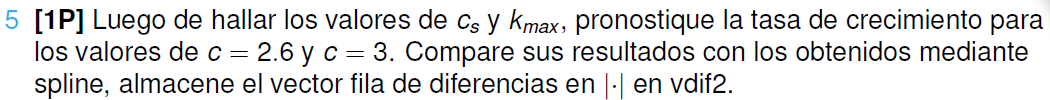

%Solución
k_max = solu_gs(1);
c_s = solu_gs(2);
k = @(c)((k_max .* c .* c)/(c_s + c .* c))

k = function_handle with value:
    @(c)((k_max.*c.*c)/(c_s+c.*c))


k5_gs = k(2.6);
k6_gs = k(3);
k5 = k_c(4,1)*((2.6 - 2.5)^3) + k_c(4,2)*((2.6 - 2.5)^2) + k_c(4,3)*(2.6 - 2.5) + k_c(4,4);
k6 = k_c(4,1)*((3 - 2.5)^3) + k_c(4,2)*((3 - 2.5)^2) + k_c(4,3)*(3 - 2.5) + k_c(4,4);
vdif2 = [abs(k5 - k5_gs) abs(k6 - k6_gs)]

vdif2 =    0.006193680375731   0.007035498264482


### FUNCIONES EMPLEADAS

## Spline Natural

function S=splinenatural(X,Y)
N=length(X)-1; H=diff(X); E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E'); g=A\b;
g=[g0 g' gn];
for i=1:N
    S(i,1)=(g(i+1)-g(i))/(6*H(i));
    S(i,2)=g(i)/2;
    S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
    S(i,4)=Y(i);
    xx=linspace(X(i),X(i+1),100);
    yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
    plot(xx,yy), hold on
end
end

## Newton Rhapson

function z=newton(f,x0,Tol)
 syms x
 df=diff(f(x));
 dfu=matlabFunction(df);
 z=x0;
 error=1;
 while error>Tol
 x1=x0-f(x0)/dfu(x0);
 z=[z;x1];
 error=abs(x1-x0)/abs(x1);
 x0=x1;
 end
 end


## QR

function [Q R]=gs_c(A)
[m,n]=size(A);
Q=zeros(m,n);
R=zeros(n);
for j=1:n
R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
R(j,j)=norm(temp);
Q(:,j)=temp/R(j,j);
end
end

## Sustitución regresiva

function [x]=sustireg(Ea,b)
U = triu(Ea);
% U: Matriz triangular superior
[m,n]=size(U);
x=zeros(n,1);
for k=n:-1:1
x(k)=(b(k)- U(k,k+1:n)*x(k+1:n))/U(k,k);
end
end